# Initialize encoder-decoder network

% Original W-net example can be opened with:
% openExample('signal/SignalSourceSeparationWithWnetExample')

rng(3407) %For reproductability and the best results (look https://arxiv.org/abs/2109.08203)

% Define the encoder-decoder architecture
inputSize = 1;
sequenceLength = 2500;

% Input layer
layers = [
    sequenceInputLayer(inputSize, "Name", "input","MinLength",sequenceLength)

    % Encoder block 1
    convolution1dLayer(3, 64, "Padding", "same", "Name", "enc1_conv1")
    reluLayer("Name", "enc1_relu1")
    convolution1dLayer(3, 64, "Padding", "same", "Name", "enc1_conv2")
    reluLayer("Name", "enc1_relu2")
    maxPooling1dLayer(2, "Stride", 2, "Name", "enc1_pool")

    % Encoder block 2
    convolution1dLayer(3, 128, "Padding", "same", "Name", "enc2_conv1")
    reluLayer("Name", "enc2_relu1")
    convolution1dLayer(3, 128, "Padding", "same", "Name", "enc2_conv2")
    reluLayer("Name", "enc2_relu2")
    maxPooling1dLayer(2, "Stride", 2, "Name", "enc2_pool")

    % Bridge
    convolution1dLayer(3, 256, "Padding", "same", "Name", "bridge_conv1")
    reluLayer("Name", "bridge_relu1")
    convolution1dLayer(3, 256, "Padding", "same", "Name", "bridge_conv2")
    reluLayer("Name", "bridge_relu2")

    % Decoder block 1
    transposedConv1dLayer(2, 128, "Stride", 2, "Name", "dec1_upsample")
    convolution1dLayer(3, 128, "Padding", "same", "Name", "dec1_conv1")
    reluLayer("Name", "dec1_relu1")
    convolution1dLayer(3, 128, "Padding", "same", "Name", "dec1_conv2")
    reluLayer("Name", "dec1_relu2")

    % Decoder block 2
    transposedConv1dLayer(2, 64, "Stride", 2, "Name", "dec2_upsample")
    convolution1dLayer(3, 64, "Padding", "same", "Name", "dec2_conv1")
    reluLayer("Name", "dec2_relu1")
    convolution1dLayer(3, 64, "Padding", "same", "Name", "dec2_conv2")
    reluLayer("Name", "dec2_relu2")

    % Output
    convolution1dLayer(1, 1, "Name", "final_conv")
    sigmoidLayer("Name", "sigmoid") 
];

lgraph = layerGraph(layers);
net = dlnetwork(lgraph);

## Generate data

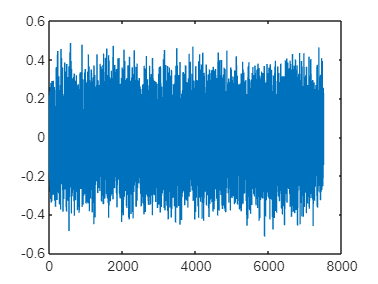

% Generate and normalize input data
input = pinknoise(1,sequenceLength*3);
input = (input -mean(input))/(max(input)-min(input));

% Visualize the input signal
figure
plot(input)

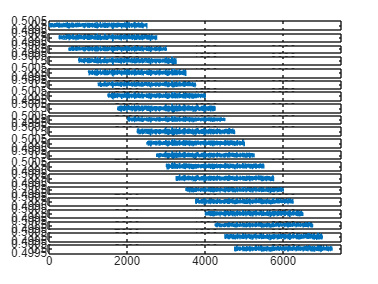


step = 250;
iterations = floor((length(input)-sequenceLength)/step);
result = nan(length(input),iterations);
% Run network over the input signal with step
for i=1:iterations
    start = (i-1)*step +1;
    stop = start + sequenceLength-1;
    [result(start:stop,i),~] = predict(net,input(start:stop)');
end

% Visualize model prediction
figure
for i=1:iterations
    a(i) = subplot(iterations,1,i);
    plot(1:length(input),result(:,i))
end
linkaxes(a,'x')

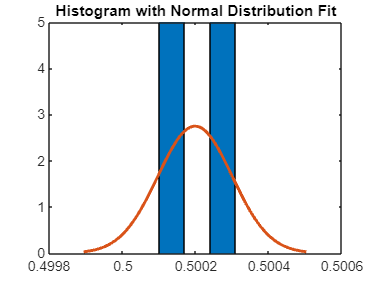


% Compute mean and standard deviation for each time step
m = zeros(1,step*iterations+sequenceLength);
s = zeros(1,step*iterations+sequenceLength);
for i=1:(step*iterations+sequenceLength)
    row = rmmissing(result(i,:));
    m(i) = mean(row);
    s(i) = std (row);
end

% Plot a histogram with a normal distribution fit
index = 2450;
distribution = result(index,~isnan(result(index,:)));
figure
histfit(distribution, 3, 'normal'); 

title('Histogram with Normal Distribution Fit');

## Plot confidence plot

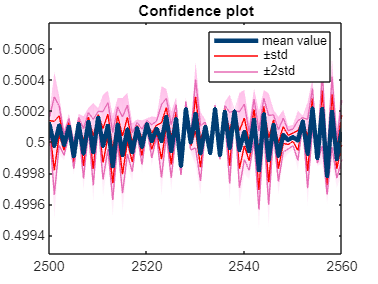

% Plot confidence intervals around the mean prediction

index = find(~isnan(m));

y = m(index);
x = 1:length(index);

% Define area for ±3 standard deviations
confidences = s(index) * 3;
xconf = [x x(end:-1:1)];
yconf = [y+confidences y(end:-1:1)-flip(confidences)];

% Create a colormap from red to white (or any two colors)
cmap = [linspace(1,1,length(xconf))', linspace(0.7,1,length(xconf))', linspace(0.9,1,length(xconf))'];

% Create gradient background for confidence area
p = patch('XData', xconf, 'YData', yconf, 'FaceVertexCData', cmap, ...
          'FaceColor', 'interp', 'EdgeColor', 'none');

% Plot ±1 and ±2 standard deviation lines
sp1 = y+s(index); sm1 = y-s(index);
sp2 = sp1+s(index); sm2 = sm1-s(index);

    
hold on
h1 = plot(x,sm1, 'r');
h2 = plot(x,sp1, 'r');

h3 = plot(x,sm2, 'Color',[0.9 0.42 0.71]);
h4 =  plot(x,sp2, 'Color',[0.9 0.42 0.71]);

h5 = plot(x,y,'linewidth',3, 'Color',[0, 62, 116] / 255);
hold off

title('Confidence plot')
legend([h5,h1,h3],{'mean value', '\pmstd', '\pm2std'})

% Zoom in
xlim([sequenceLength,sequenceLength+60])
ylim([min(sm2),max(sp2)])